# Take Home Exercise - OCR

A region of interest (ROI) is a portion of an image that you want to filter or operate on in some way. In this exercise, you will be able to select a region using a mouse.

% Display image using imshow
I = imread("/MATLAB Drive/Repositories/beyond-the-label/data/images/conditioner.jpg");
imshow(I)

% Find the OCR test
ocrResults = ocr(I);
fullText = ocrResults.Text

fullText =     'INGREDIENTS/INGREDIENTS: Lactobacillus/
     Arundinaria Gigantea Ferment Filtrate, Glycerin,
     Lactobacillus Ferment, Stearyl Alcohol, Cocos
     Nucifera (Coconut) Fruit Extract, Squalane,
     Bambusoides Extract, Salvia
     Hispanica Seed Extract,  Sacchar
     Cerevisiae Extract, Behentrimonium Methosulfate,
     Cyamopsis Tetragonoloba (Guar) Gum, PCA
     Glyceryl Oleate, Selaginella Lepidophylla Extract,
     Cetyl Alcohol, Euterpe Oleracea Sterols, Fragrance
     (Parfum)*, Linalool, Butylene Glycol, Limonene,
     Linoleic Acid, Oleic Acid, Citral, Linolenic Acid
     *Naturally-denved dongine
     
     30728301
     
     '


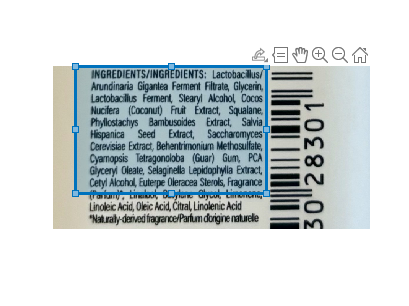


% Select the ROI using mouse and display the text in ROI
roi = drawrectangle();

ocrResultsRoi = ocr(I,round(roi.Position));
roiText = ocrResultsRoi.Text

roiText =     'INGREDIENTS/INGREDIENTS: Lactobacillus/
     Aundinaria Gigantea Ferment Filtrate, Glycerin,
     
     Hispanica
     Cerevisiae Extract, Behentrimonium Methosul
     Cyamopsis Tetragonoloba (Guar) Gum, PCA
     
     '
